Příklady k Procvičení:

clear all;
close all;

# Výběrové charakteristiky

## 1. Výběrové charakteristiky

Příklad 1: 

- Vygenerujte 10000 náhodných čísel z rovnoměrného rozdělení <0,1> a vytvořte histogram o 100 sloupcích, které vynesete do grafu 1. 

- Dále vygenerujte 10000 dvojic náhodných čísel, které sečtete a vydělíte dvěma. Opět vyneste histogram o 100 sloupcích do grafu 2.

- Obdobně vygenerujte 10000 pětic náhodných čísel, které sečtete a vydělíte pěti. Opět vyneste histogram o 100 sloupcích do grafu 3.

- Obdobně vygenerujte 10000 desetic náhodných čísel, které sečtete a vydělíte pěti. Opět vyneste histogram o 100 sloupcích do grafu 4.

- Vysvětlete, proč data se „shlukují“ v blízkosti střední hodnoty. 

Všimněte si, že 1) se zvyšujícím se počtem vygenerovaných dat se více podobají normálnímu rozdělení, 2) blíží se k průměru a zmenšuje se rozptyl...

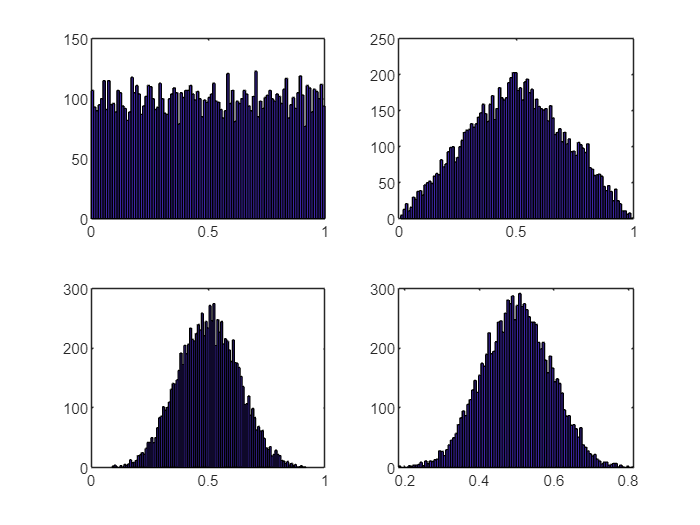

clear a b c d b_new c_new d_new
%a)
a = rand(10000,1);
figure
subplot(2,2,1)
hist(a,100)

B=rand(10000,2);
for i=1:10000
    B_new(i)=(B(i,1)+B(i,2))/2;
end
subplot(2,2,2)
hist(B_new,100)

%vygeneruji n�hodn� ��sla z dvojic z rovnom�rn�ho rozd�len�
B=rand(10000,5);
for i=1:10000
    B_new(i)=sum(B(i,:))/5;
end
subplot(2,2,3)
hist(B_new,100)

%vygeneruji n�hodn� ��sla z desetic z rovnom�rn�ho rozd�len�
B=rand(10000,10);
for i=1:10000
    B_new(i)=sum(B(i,:))/10;
end
subplot(2,2,4)
hist(B_new,100)

Příklad 2: Vygenerujte 1000000 desetic náhodných čísel z rovnoměrného rozdělení <0,1>. Prvky v deseticích sečtěte a vyneste do histogramu o 1000 sloupcích. Zároveň do stejného grafu vyneste hustotu pravděpodobnosti normálního rozdělení s parametry N($\left.\mu =5;\ \sigma^2 =\frac{10}{12}\right)$, kterou vynásobíte 8000. Vysvětlete, proč se obě funkce tvarově relativně dobře překrývají. 

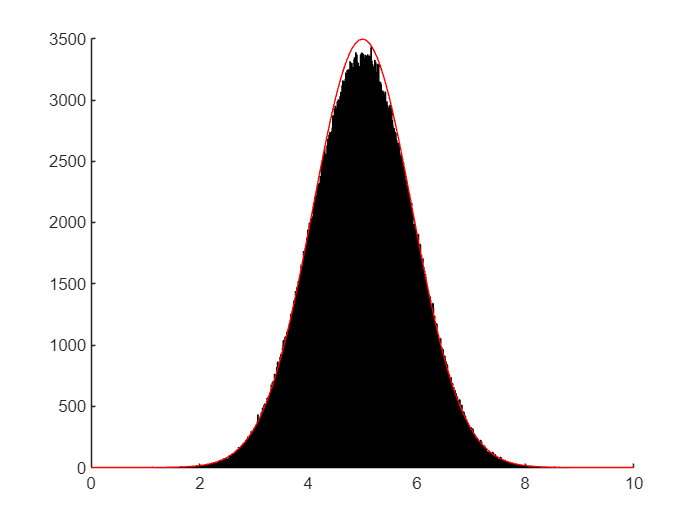

B=rand(1000000,10);
for i=1:1000000
    B_new(i)=sum(B(i,:));
end

x=0:0.01:10;
fx=8000*normpdf(x,5,sqrt(10/12));
figure
hold on
hist(B_new,1000)
plot(x,fx,'r')


hold off

Příklad 3: Vygenerujte 10000 čísel z normálního rozdělení s parametry N($\left.\mu =5;\ \sigma^2 =4\right)$a vyneste je do grafu ve formě histogramu o 100 sloupcích. Do druhého obdobného grafu vyneste vygenerovaných 10000 čísel z normálního rozdělení s parametry N($\left.\mu =-5;\ \sigma^2 =4\right)$.

Odhadněte, jaké parametry bude mít rozdělení, jestliže hodnoty sečtete. Ověřte výpočtem správnost Vašeho řešení. 

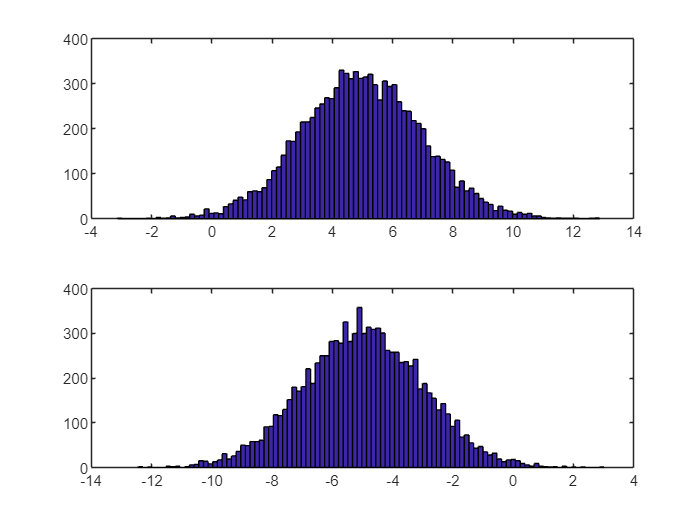

x = normrnd(5,2,10000,1);
figure
subplot(2,1,1)
hist(x,100)

y = normrnd(-5,2,10000,1);
subplot(2,1,2)
hist(y,100)


z = x+y;
[mu,sigma]=normfit(z)

mu = -0.0136

sigma = 2.7806

Příklad 3a: Vygenerujte 10000x1000 dat z logaritmicko normálního rozdělení (značně nesymetrické) s parametry $\mu =3;\ \sigma^2 =4$. V řádku hodnoty sečtěte a udělejte z nich průměr, který vynesete do histogramu o 100 sloupcích. 

Všimněte si, že i průměr značně nesymetrických vstupních dat může se blížit normálnímu rozdělení.

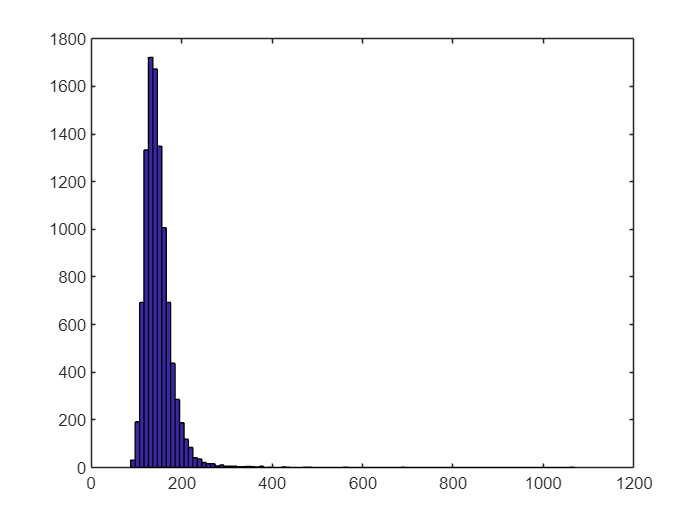

clear x
x = lognrnd(3,2,10000,1000);
for i=1:10000
    x_new(i) = sum(x(i,:))/1000;
end
figure
hist(x_new,100)

Příklad 4: Náhodná veličina A má E(X)=5 a D(X)=4, náhodná veličina B má E(X)=3 a D(X)=6, náhodná veličina C má E(X)=2 a D(X)=8. (Jsou nezávislé.) Vypočtěte střední hodnotu a rozptyl výsledné náhodné veličiny X, která je dána vzorcem X=A+B+C a Y=A+B-C.

EX = 5+3+2

EX = 10

DX = 4+6+8

DX = 18

EY = 5+3-2

EY = 6

DY = 4+6+8

DY = 18

Příklad 6:  Náhodná veličina A má E(X)=5 a D(X)=4, náhodná veličina B má E(X)=0 a D(X)=16. Vypočtěte střední hodnotu a rozptyl výsledné náhodné veličiny X, která je dána vzorcem X=A+3*B.

EX = 5 + 3*0;
DX = 4 + 3^2*16

DX = 148

## 2. Centrální limitní věta

Příklad 7: Máte vygenerováno 1000 náhodných čísel z rovnoměrného rozdělení <0,1>. Určete pravděpodobnost, že průměr všech vygenerovaných čísel bude vyšší než 0.520.

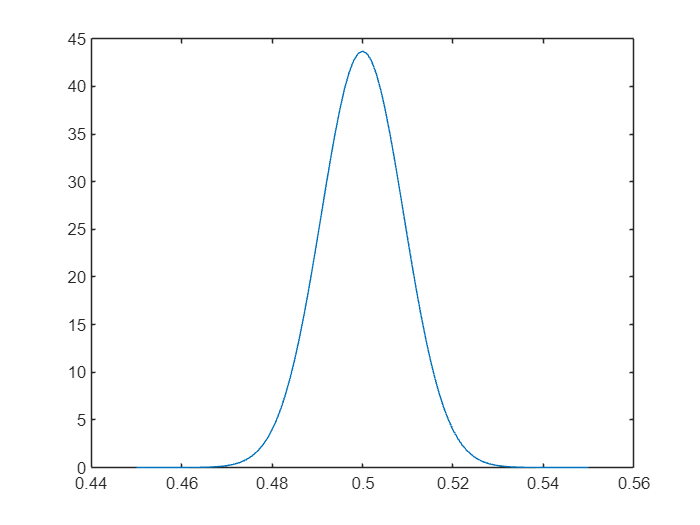

clear x
X = rand(1000);
mu = 0.5;
sigma = sqrt((1/12)/1000);
x = 0.45:0.001:0.55;
y = normpdf(x,mu,sigma);
figure
plot(x,y)

P = 1-normcdf(0.520,mu,sigma)

P = 0.0142

Příklad 8: Životnost komponenty má exponenciální rozdělení se střední hodnotou 5 let. Určete pravděpodobnost, že 100 náhodně vybraných komponent bude mít v průměru životnost nižší než 4 roky.

str_hod = 5;
mu = (100*str_hod)/100;
sigma = sqrt((str_hod^2)/100);
no = normcdf(4,mu,sigma), P = no

no = 0.0228

P = 0.0228

Příklad 9: Zatížení letadla s 64 místy nemá překročit 6000 kg. Jaká je pravděpodobnost, že při plném obsazení bude tato hodnota překročena, má-li hmotnost cestujícího střední hodnotu 90 kg a směrodatnou odchylku 10 kg.

mu = 90*64;
sigma = sqrt(10^2*64);

P=1-normcdf(6000,mu,sigma)

P = 0.0013

Příklad 10: Počet chyb na jedné straně textu má střední hodnotu 3 a rozptyl 4. Jaká je pravděpodobnost, že na 400 stranách bude méně než 1000 chyb. 

mu = 3*400;;
sigma=sqrt((4*400));
P = normcdf(1000,mu,sigma)

P = 2.8665e-07

Příklad 11: Stokrát hodíme šestistěnnou kostkou. Jaká je pravděpodobnost, že součet hodů bude mezi 320 a 380.

str_hod = (1+2+3+4+5+6)/6;
rozptyl = 2*((1-str_hod)^2+(2-str_hod)^2+(3-str_hod)^2)/6;
mu = str_hod*100;
sigma = sqrt(rozptyl*100);
P = normcdf(380,mu,sigma) - normcdf(320, mu, sigma)

P = 0.9210

Příklad 12: 600 krát hodíme kostkou. Pomocí binomického rozdělení, Poissonova rozdělení a centrální limitní věty určete, jaká je pravděpodobnost, že šestka padne 105 a vícekrát. 

n= 600;
p = 1/6;
Pa = 1-binocdf(104.5, n, p)

Pa = 0.3078

lambda = n*p;
Pb = 1 - poisscdf(104.5,lambda)

Pb = 0.3216

mu = n*p;
sigma = sqrt(n*p*(1-p));
Pc = 1 - normcdf(104.5,mu, sigma)

Pc = 0.3110

Příklad 13: V osudí je 16 bílých a 14 černých koulí. Jaká je pravděpodobnost, že při 150 tazích jedné koule (s vracením) vytáhneme bílou právě 77x.

- Řešte pomocí binomického rozdělení.

- Řešte pomocí Poissonova rozdělení.

- Řešte pomocí centrální limitní věty. 

n = 150;
p = 16/30;
Pa = binopdf(77,n,p)

Pa = 0.0577

lambda = n*p;
Pb = poisspdf(77,lambda)

Pb = 0.0429

mu = n*p;
sigma = sqrt(mu*(1-p));
Pc = normpdf(77,mu, sigma)

Pc = 0.0579

## 3. Rozdíl výběrových průměrů

Příklad 14: Průměrný plat v České republice je 27 000 Kč se směrodatnou odchylkou 8000 Kč. Průměrné náklady na bydlení jsou 7000 Kč se směrodatnou odchylkou 2000 Kč. Vypočtěte pravděpodobnost, že člověku zůstane alespoň 25000 Kč, jestliže z platu odečteme náklady na bydlení. 

mu = 27000 - 7000;
sigma =sqrt(8000^2+2000^2);
Pa = 1 - normcdf(25000,mu,sigma)

Pa = 0.2721

Příklad 15: Př. 15: V roce 2015 a 2016 probíhal průzkum ohledně měsíčních výdajů za pivo. Zjistěte pravděpodobnost, že v roce 2016 dávají lidé za pivo více než v roce 2015.   

x2015=[587,124,651,1212,1074,523,273,800,485,961,1683,2411]

x2016=[121,524,2612,847,1310,1521,951,1000,521,12,190,263,321,587,953]

x2015 = [587,124,651,1212,1074,523,273,800,485,961,1683,2411];
x2016 = [121,524,2612,847,1310,1521,951,1000,521,12,190,263,321,587,953];

mu2015=mean(x2015);
mu2016=mean(x2016);
var2015=var(x2015);
var2016=var(x2016);

P=1-normcdf(0,mu2016-mu2015,sqrt(var2015/length(x2015)+var2016/length(x2016)))

P = 0.3229

Příklad 17: Zeptali jsme se 1000 respondentů na oblibu místního cholerického politika. Obdrželi jsme kladný výsledek od 168 respondentů. Místní cholerický politik však říká, že jeho obliba je 55 procent. Určete pravděpodobnost, že jeho tvrzení je pravdivé a jeho obliba je 55 %.

n = 1000;
p = 0.168;
pi = 0.55;

%vypočtu z, které je z N(0,1) z něj následně pravděpodobnost
z = (p-pi)/sqrt(pi*(1-pi)/n);
P = normcdf(z,0,1)

P = 1.5369e-130

Příklad 18: Zeptali jsme se 1000 respondentů na určitý výrok. 60 % řeklo, že s ním souhlasí. Určete pravděpodobnost, že po zeptání celé společnosti bude výsledek minimálně: 45%, 50%, 55%, 59 %, 60 %, 61 %, 65 %, 70 %. 

Porovnejte výsledky mezi sebou. Lze vidět, že výsledné pravděpodobnosti 45 % i 70 % jsou velmi málo pravděpodobné.

n = 1000;
pi = 0.60;
p = [0.45,0.50,0.55,0.59,0.60,0.61,0.65,0.70]

p =     0.4500    0.5000    0.5500    0.5900    0.6000    0.6100    0.6500    0.7000


z=(p-pi)./sqrt(pi.*(1-pi)./n);
P = 1 - normcdf(z,0,1,1,length(z))

P =     1.0000    1.0000    0.9994    0.7407    0.5000    0.2593    0.0006    0.0000


Příklad 19: Jak se změní výsledky z příkladu 18, jestliže se zeptáme pouze 100 lidí?

n = 100;
z=(p-pi)./sqrt(pi.*(1-pi)./n);
P = 1 - normcdf(z,0,1,1,length(z))

P =     0.9989    0.9794    0.8463    0.5809    0.5000    0.4191    0.1537    0.0206


Příklad 20: V roce 2015 jsme se zeptali 250 respondentů na určitý názor – 62 odpovědělo souhlasně. Obdobně v roce 2016 jsme se zeptali 340 respondentů na stejnou otázku – 141 odpovědělo souhlas. Zjistěte pravděpodobnost, že rozdíl výběrových četností roků 2016 a 2015 je kladný.  

n15 = 250;
p15 = 62/250;
n16 =340;
p16 = 141/340;

pi = 0;
z = (p16 - p15)/sqrt((p16*(1-p16)/n16) + (p15*(1-p15)/n15));
P = normcdf(z,0,1)

P = 1.0000

Příklad 21: Řešte př. 20 s následující úpravou.  Určete pravděpodobnost, že se zvýšila podpora tohoto názoru minimálně o 10 %.

pi = 0.10;
z = (p16 - p15 - pi)/sqrt((p16*(1-p16)/n16) + (p15*(1-p15)/n15));
P = normcdf(z,0,1)

P = 0.9596

## 4. $\chi^2$ rozdělení

Příklad 22: Zjistěte 5 a 95% kvantil chí kvadrát rozdělení s 10 stupni volnosti

q5 = chi2inv(0.05, 10)

q5 = 3.9403

q95 = chi2inv(0.95,10)

q95 = 18.3070

Příklad 23: Vykreslete graf hustoty pravděpodobnosti pro chí kvadrát rozdělení s 2, 4 a 6 stupni volnosti.

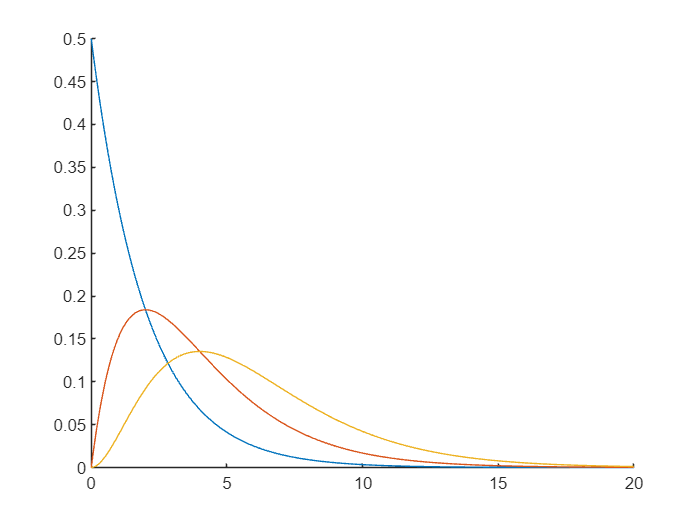

clear x
x = 0:0.05:20;
figure
hold on
y = chi2pdf(x,2);
plot(x,y)
y = chi2pdf(x,4);
plot(x,y)
y = chi2pdf(x,6);
plot(x,y)
hold off 

Příklad 24: Mějme dat az $\chi^2$ rozdělení s 12 stupni volnosti. Určete pravděpodobnost: P(X > 20). 

P = 1 - chi2cdf(20, 12)

P = 0.0671

## 5. Studentovo rozdělení (t-rozdělení)

Příklad 25: Určete pravděpodobnost, že Studentovo rozdělení s 2, 4, 10, 100 stupni volnosti nabývá P(X > 1). Určete pravděpodobnost i pro normované normální rozdělení. 

P5(1) = 1 - tcdf(1,2);
P5(2) = 1 - tcdf(1,4);
P5(3) = 1 - tcdf(1,10);
P5(4) = 1 - tcdf(1,100);
P5(5) = 1 - normcdf(1,0,1)

P5 =     0.2113    0.1870    0.1704    0.1599    0.1587


Příklad 26: Zjistěte 5 a 95% kvantil Studentova rozdělení s 10 stupni volnosti.

q5 = tinv(0.05,10)

q5 = -1.8125

q95 = tinv(0.95,10)

q95 = 1.8125

Příklad 27: Vykreslete graf hustoty pravděpodobnosti pro Studentovo rozdělení s 1, 2 a 4 stupni volnosti. Do jednoho grafu nakreslete zároveň hustotu pravděpodobnosti normovaného normálního rozdělení. Uvědomte si, že Studentovo rozdělení konverguje k normovanému normálnímu, jestliže stupeň volnosti se blíží $\infty$.

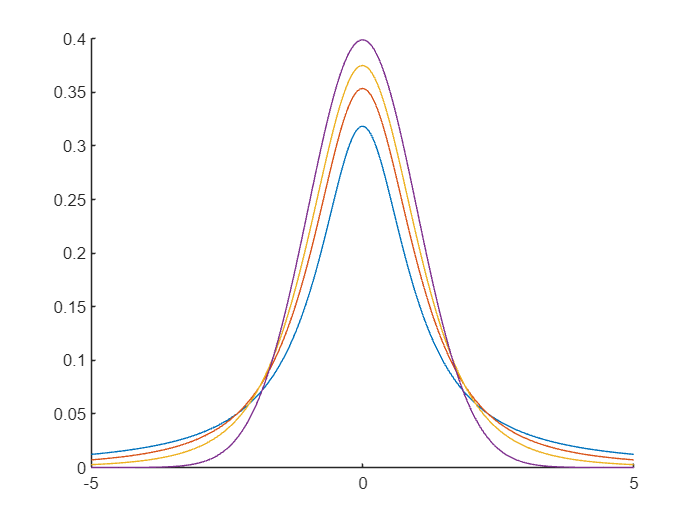

clear x
x = -5:0.01:5;

figure
hold on
y = tpdf(x,1);
plot(x,y)
y = tpdf(x,2);
plot(x,y)
y = tpdf(x,4);
plot(x,y)
y = normpdf(x,0,1);
plot(x,y)
hold off

## 6. Fisher-Snedecorovo rozdělení (F rozdělení)

Příklad 28: Zjistěte 5 a 95 % kvantil F rozdělení s 10 a 5 stupni volnosti. Dále určete 5 a 95% kvantil F rozdělení s 5 a 10 stupni volnosti. Zkuste odhadnout jaký je mezi výsledky vztah.

q5_1 = finv(0.05,10,5)

q5_1 = 0.3007

q95_1 = finv(0.95,10,5)

q95_1 = 4.7351


q5_2 = finv(0.05,5,10)

q5_2 = 0.2112

q95_2 = finv(0.95,5,10)

q95_2 = 3.3258